# Verificação nFOC

Recomendo antes de ir direto para o código, entender um pouco como funciona a definição do problema, ao contrário dos outros, aqui trabalhamos com o contorno e não com a região em si

clear;
gamaf = 1.5;
gamac = 1.5;
gamas = 1.15;
Es = 210*10^3;

###  Definição dos parâmetros do concreto

tipoc = 60; %definicoes de material %esta em MPa
tipos = 50; %nao esta em MPa

[etac,sigmacd,epsilonc2,epsiloncu,n] = paramsConcreto(tipoc,gamac);
[fyd,epsilonyd] = paramsaco(tipos,Es,gamas);

Para definir as coordenadas do aço, escolha um ponto arbitrário para começar, por exemplo C.G. (centro geométrico) da estrutura ou até mesmo uma quina, percorra no sentido antihorário e anote as coordenadas e preencha o vetor

%----------Definição área aço

xs = [3 12 17 17 12 12 3 3]/100;
ys = [3 3 3 12 12 27 27 12]/100;


diametro = 20* 10^-3; 
As = 0.25*diametro^2*pi*(ones(1,length(xs)));

No caso do concreto definimos o contorno

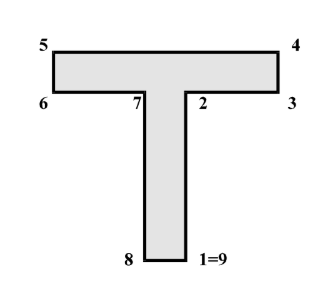

Percorremos os pontos e seguimos as coordenadas no sentido anti-horário, anotando as coordenadas a partir do mesmo ponto que utilizamos para , para fechar o polígono repetimos o primeiro elemento, nesse código não é necessário então preencha todos os pontos sem repetir

x = [0 20 20 15 15 0]/100;
y = [0 0 15 15 30 30]/100;

Essa linha é responsável por fechar o polígono

x = [x x(1)];
y = [y y(1)];

Translação das coordenadas para o CG e caso seja preenchido no sentido errado,códgio de correção


if (A_c(x,y) < 0) % Resolvendo o problema do sentido
    x= flip(x);
    y = flip(y);
end

numero_arestas = length(x)-1;
[x,y,xs,ys] = translacao_CG(x,y,numero_arestas,xs,ys);


Definição dos esforços solicitantes 

Nd = 2;
Mxd = 0.08;
Myd = 0;

Definição da Precisão

precisao = 1e-13;
tolerancia = 1e-13;

Chutes Iniciais

epsilon0 = 0.0; %chute inicial de epsilon0
kx = 0.0; %chute inicial da curvatura
ky = 0.0;

A lógica é a mesma da Verificação do FNC, com algumas ressalvas em como definimos os esforços e a Jacobiana

Nesse caso o código trabalha fundamentado nessa deformação:

Sendo i, os pontos definidos no concreto, pois trabalharemos percorrendo o contorno

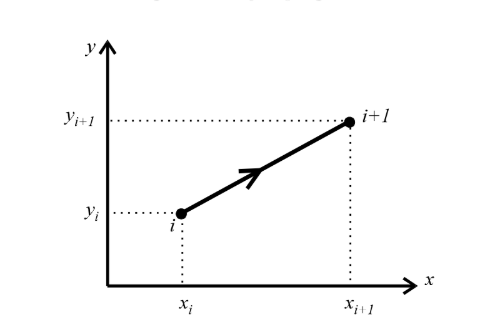

Percorrendo por exemplo de 1 até 11 nesse caso, e cada i seria um ponto

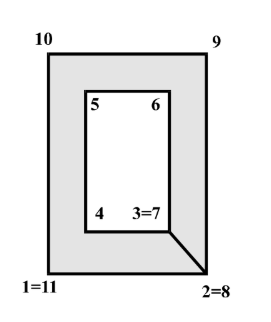

### Para o concreto

N_c = Nc(sigmacd,epsilon0,kx,ky,x,y);
M_cx = Mcx(sigmacd,epsilon0,kx,ky,x,y);
M_cy = Mcy(sigmacd,epsilon0,kx,ky,x,y);

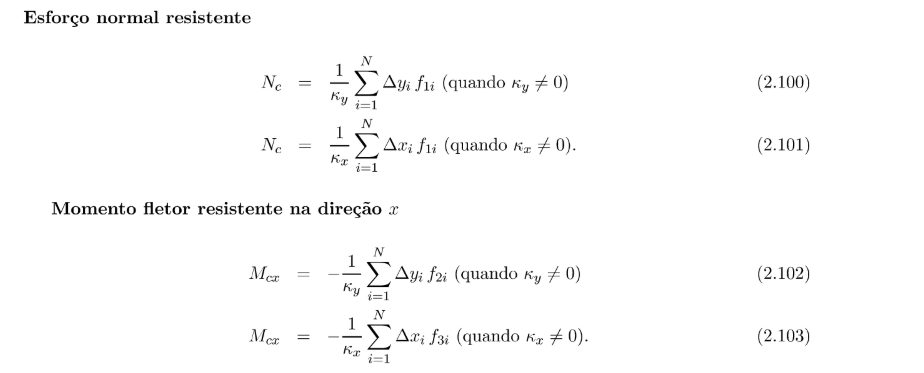

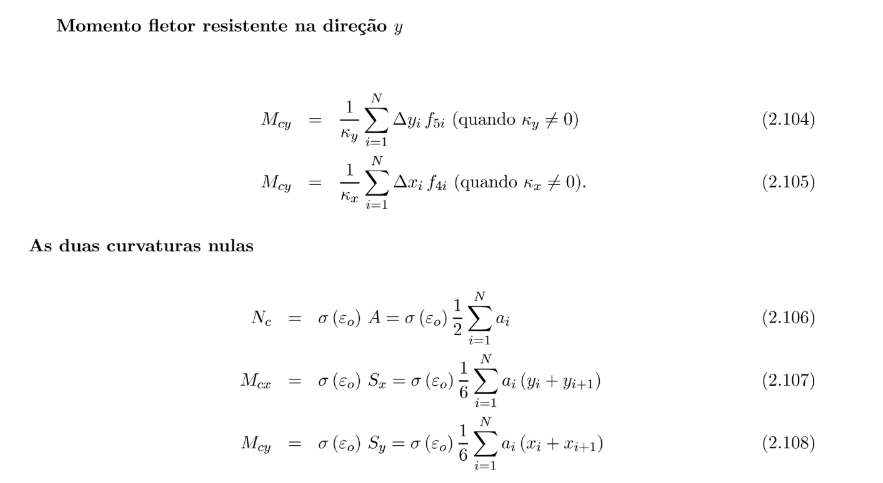

### Definições Aplicadas

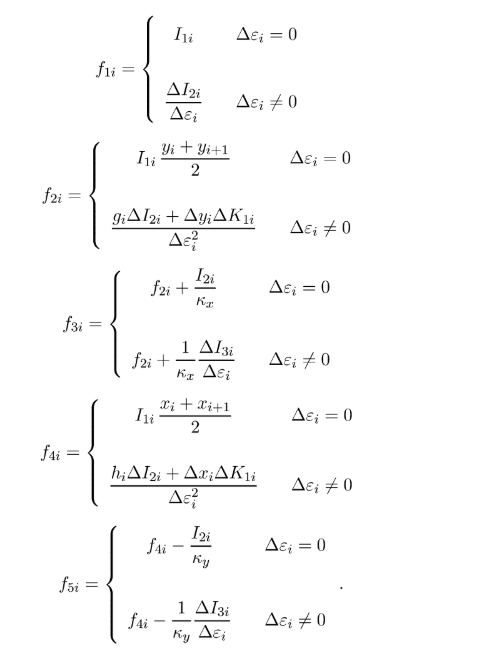

Mais definições 

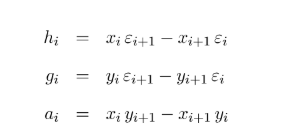

Mais definições ainda 

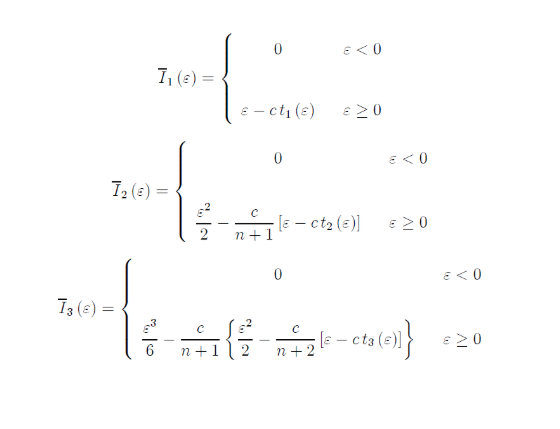

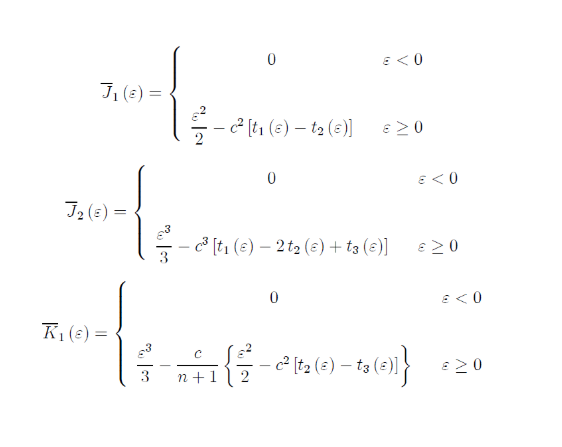

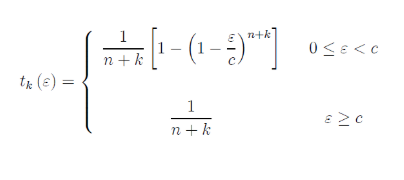

Lembrando que para o concreto:

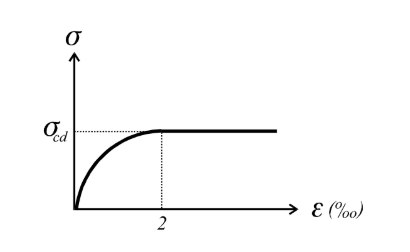

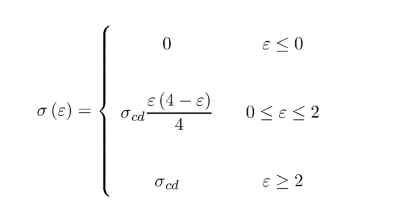

[Ns, Msx, Msy] = esforcos_aco(epsilon0,kx,ky,xs,ys,As,fyd,epsilonyd);

Para o aço:

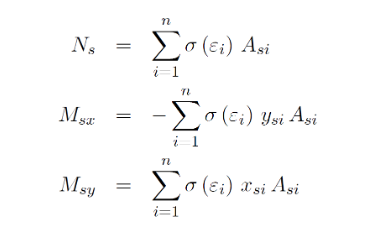

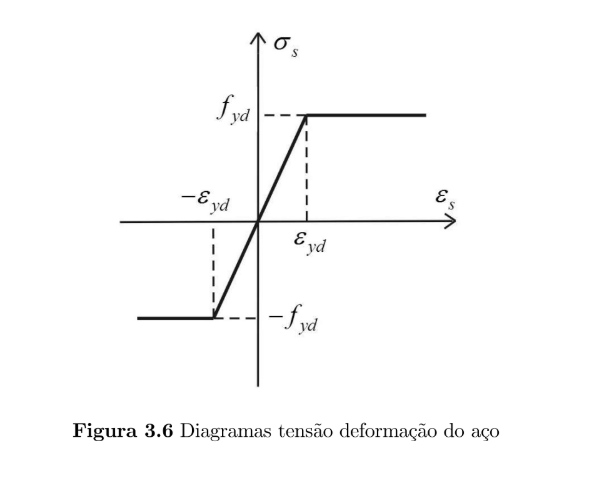

Nr = N_c + Ns;
Mxr = M_cx + Msx;
Myr = M_cy + Msy;

Para essa Jacobiana preferimos separar em Jacobiana do Aço e Jacobiana do Concreto

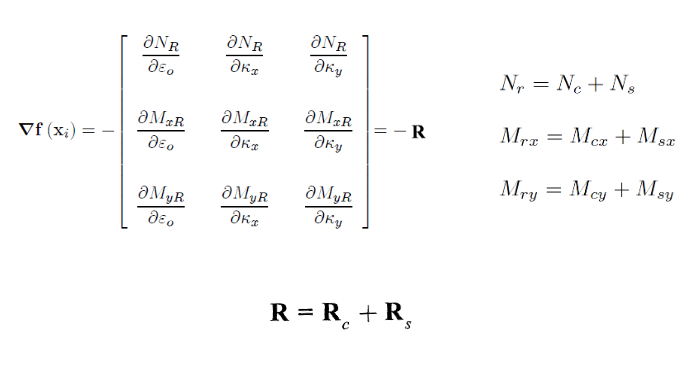

### Jacobiana Aço

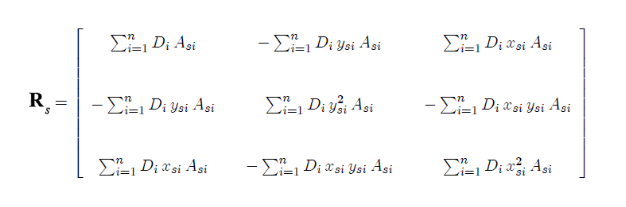

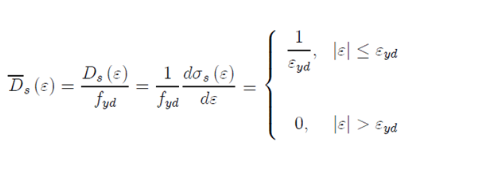

### Jacobiana Concreto

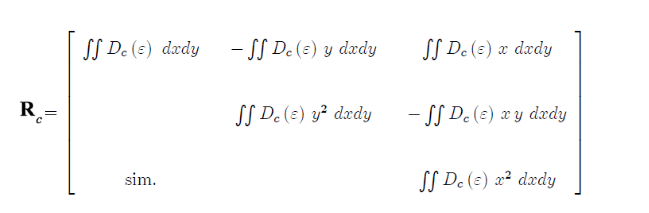

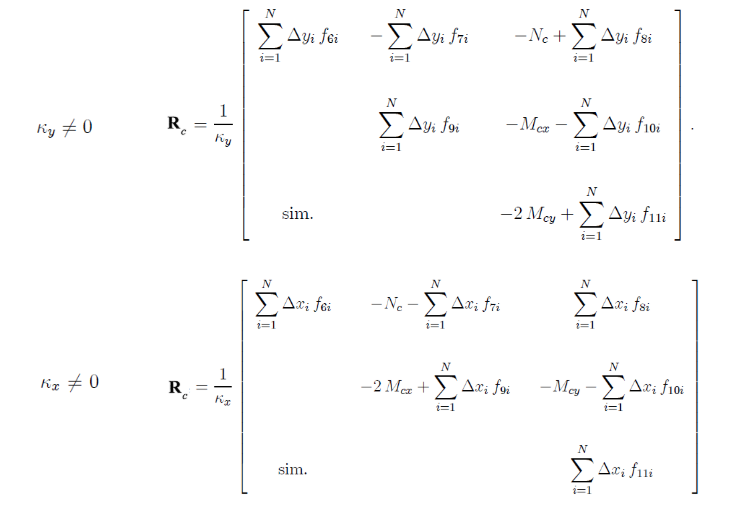

Mais definições:

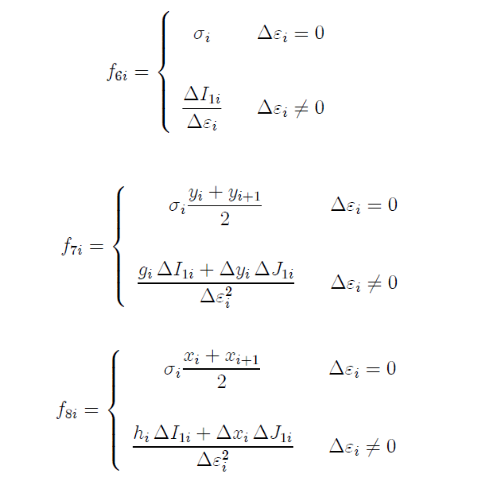

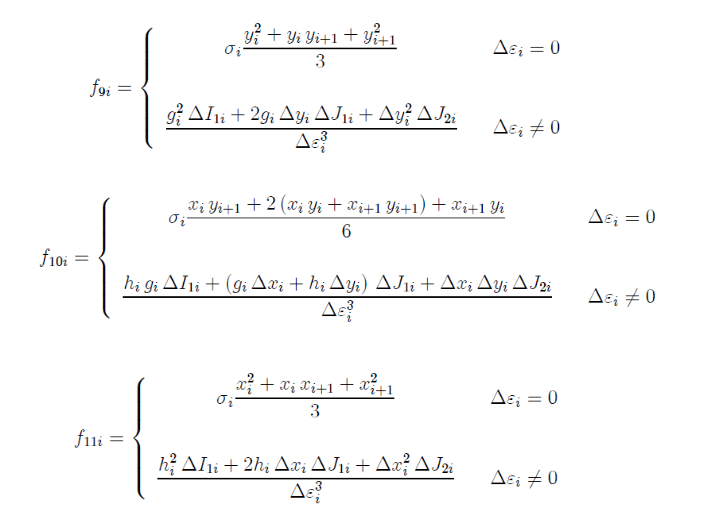

Mais definições:

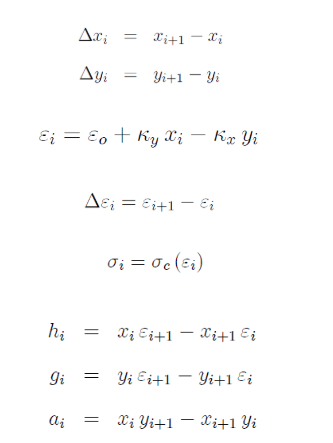

J = matR(sigmacd,x,y,epsilon0,kx,ky,epsilonc2,n) + matRs(As,xs,ys,epsilon0,kx,ky, epsilonyd,fyd); %matR é concreto
f = sqrt( (Nd - Nr)^2 +  (Mxd - Mxr)^2 + (Myd - Myr)^2);

cont =1;
maxit = 1000;

while cont <= maxit && f >= tolerancia
    % Verifique a singularidade da matriz Jacobiana
    
    Det = det(J);

    if abs(Det) < tolerancia
        warning('A matriz Jacobiana está próxima de ser singular. Iteração interrompida.');
        break;
    end
    
    % Calcular a inversa de J e atualizar as variáveis
    
    f_x = [Nd-Nr Mxd-Mxr Myd-Myr];

    auxiliar = inversor_matriz(J,f_x);
    epsilon0 = epsilon0 - auxiliar(1)/det(J);
    kx = kx - auxiliar(2)/det(J);
    ky = ky - auxiliar(3)/det(J);
    
    
    % Calcular novos resultados
    [Ns, Msx, Msy] = esforcos_aco(epsilon0, kx, ky, xs, ys, As, fyd, epsilonyd);

    Nr = Nc(sigmacd, epsilon0, kx, ky, x, y,n,epsilonc2) + Ns;
    Mxr = Mcx(sigmacd, epsilon0, kx, ky, x, y,n,epsilonc2) + Msx;
    Myr = Mcy(sigmacd, epsilon0, kx, ky, x, y,n,epsilonc2) + Msy;

    % Atualizar a matriz Jacobiana e a norma do vetor de resíduos
    J = matR(sigmacd,x,y,epsilon0,kx,ky,epsilonc2,n) + matRs(As, xs, ys, epsilon0, kx, ky, epsilonyd, fyd);
    f = sqrt((Nd - Nr)^2 + (Mxd - Mxr)^2 + (Myd - Myr)^2);
    
    % Incrementar o contador
    cont = cont + 1;
end

Verificando se o sistema achou solução

if (cont >= maxit || abs(det(J)) <= tolerancia)
    fprintf("Não é possivel achar a solução. A seção não resiste aos esforços \n");
    return
end

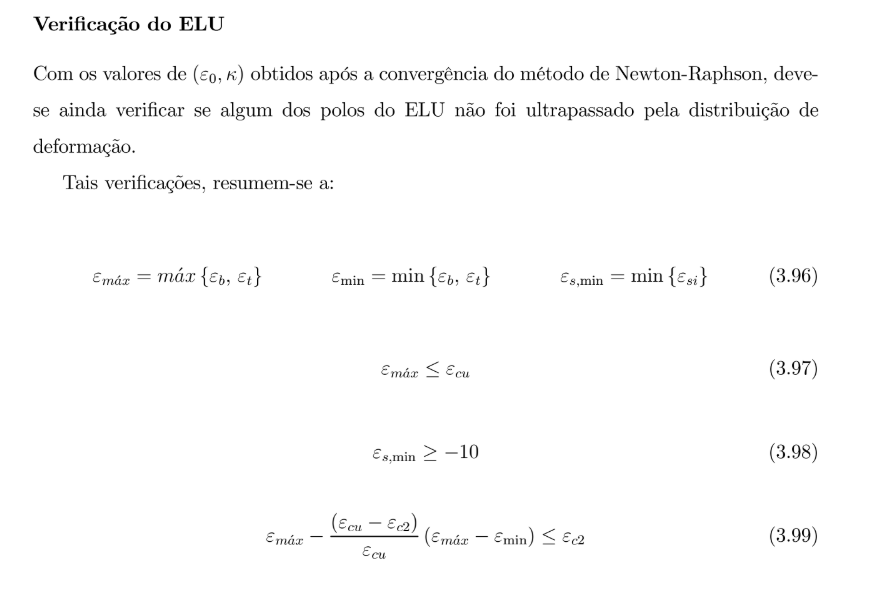


e_arestas = zeros(1, length(x));
for i = 1:length(x)
    e_arestas(i) = epsilon0 + ky*x(i) - kx*y(i);
end
e_max = max(e_arestas);
e_min = min(e_arestas);
e_si = zeros(1, length(xs));

for j = 1:length(xs)
    e_si(j) = epsilon0 + ky*xs(j) - kx*ys(j) ;
end

e_s_min = min(e_si);

Verificando qual caso recaimos

if (e_max <= epsiloncu && e_s_min >= -10 && e_max - (epsiloncu - epsilonc2)/epsiloncu*(e_max - e_min) <= epsilonc2)
    fprintf("Solução viável.\n\nA configuração de deformação é (epsilon0,kx,ky) = (%.6f, %.6f, %.6f) \n",epsilon0,kx,ky);
else
    disp("Solução equilibra a seção, mas não é viável.")
end

Solução equilibra a seção, mas não é viável.


## Caso especial

### Parametrização Circular

A parametrização circular consiste no conceito de determinar pontos de geometria para definir um círculo

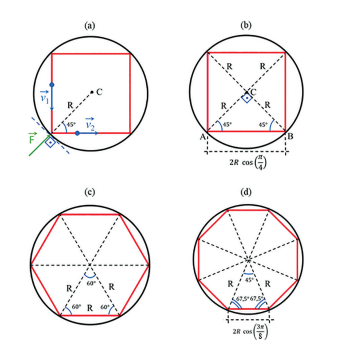

raio_arestas = 0.1;
raio_armaduras = 0.07;
N_pontos = 50; 
[x_arestas, y_arestas] = parametrizacao_circular(0, 0, raio_arestas, N_pontos, true);
[x_s, y_s] = parametrizacao_circular(0, 0, raio_armaduras, numero_barras, false);